Calculando o Tau e o Kcc

opts = detectImportOptions('dados_aquecedor_matlab.csv');
T = readtable('dados_aquecedor_matlab.csv', opts);
time = T.time;
temp_offset = T.temp_offset;

% Achando tau e o ganho Kcc
stable_temperature = 26.0;
aux_temp = stable_temperature * 0.632; 
[~, idx] = min(abs(temp_offset - aux_temp));
tau = time(idx);
Kcc = stable_temperature/0.015;
disp(['Tau: ', num2str(tau)]);

Tau: 930


disp(['Kcc: ', num2str(Kcc)]);

Kcc: 1733.3333


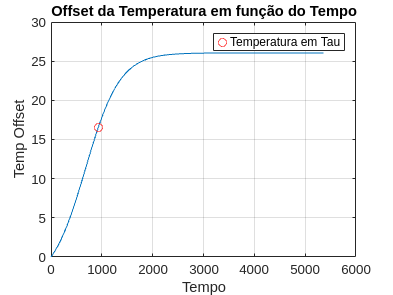



plot(time, temp_offset);
hold on;
temp_offset_at_tau = temp_offset(idx);
plot(tau, temp_offset_at_tau, 'ro'); % Destacar o ponto
title('Offset da Temperatura em função do Tempo');
legend('', 'Temperatura em Tau');
xlabel('Tempo');
ylabel('Temp Offset');
grid on;
hold off;

Achando a função de transferencia

s = tf('s');

% Kcc = Resistencia Termica
% Tau = Resistencia Termica * Capacitancia Termica
G = Kcc / (tau*s + 1)


G =
 
    1733
  ---------
  930 s + 1
 
Continuous-time transfer function.
Model Properties


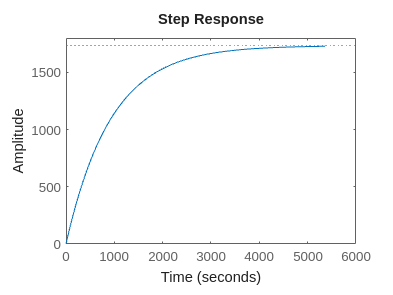

step(G, time);

Aplicando o Ganho Potencia Elétrica e Ganho Kph

Kpe = 32^2 / 16.129  % tensão usada no variac ao quadrado sobre a resistencia

Kpe = 63.4881

Kph = 2.39 * 10^(-4)

Kph = 2.3900e-04

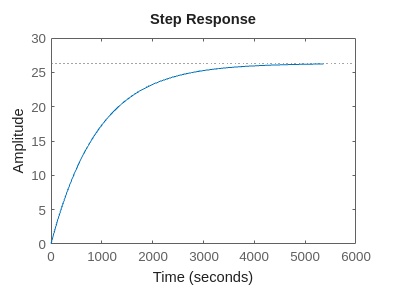

step(Kpe * Kph * G, time);

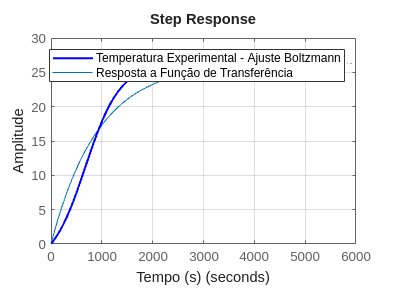


figure;
plot(time, temp_offset, 'b', 'LineWidth', 1.5); % Plota o sinal contínuo
hold on;
step(Kpe * Kph * G, time);
hold off;

xlabel('Tempo (s)');
ylabel('Amplitude');
title('Step Response');
legend('Temperatura Experimental - Ajuste Boltzmann', 'Resposta a Função de Transferência');
grid on;